# Synergistic Hybrid Feedback for Robust Global Obstacle Avoidance

This MATLAB Live Script describes the implementation of the robust synergistic controller of the paper 

"Robust Hybrid Synergistic Feedback", P. Casau, R.G. Sanfelice, and C. Silvestre.

More specifically, its application to the global asymptotic stabilization of a setpoint on the plane in the presence of an obstacle. 

## Simulation of Hybrid Systems

*You will need to install the Hybrid Equations Toolbox to run this example.*

This is a self-contained live script in the sense that all the required functions to run this simulation are defined below. The controller and problem parameters are defined as global variables at the start. The proposed controller requires the computation of several partial derivatives and we resort to MATLAB's symbolic toolbox as much as possible to perform these computations for us.

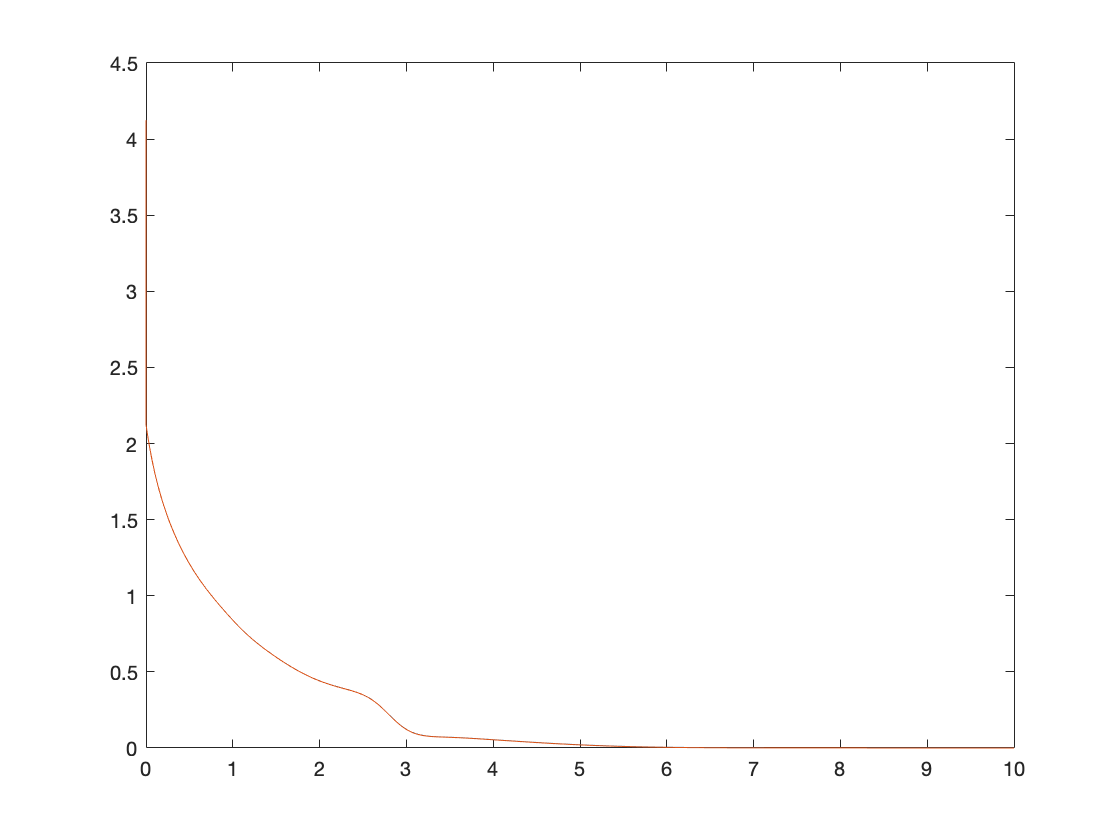

global z_0 r Gamma_1 theta_0 epsilon theta Gamma_2 k_u
z_0   = [1 0]';            % Center of the obstacle
r     = 0.5;               % Radius of the obstacle
Gamma_1 = eye(2);          % Estimator gain
Gamma_2 = eye(2);          % Backstepping gain
k_u = 1;                   % Derivative gain
theta_0 = 1;               % Maximum disturbance magnitude 
epsilon = 1;               % Proj operator parameter
theta = sqrt(2)*[1 1]'./4; % Disturbance

% Computation of partial derivatives
if ~exist('Dphi','file')
    partialDiffFnc(@(xi) phi(xi(1:3),xi(4)),[4,1],1:3,'Dphi',{1:3,4});
end
if ~exist('DV_0','file')
    partialDiffFnc(@(xi) V_0(xi(1:3),xi(4)),[4,1],1:3,'DV_0',{1:3,4});
end
if ~exist('Dxkappa_1','file')
    partialDiffFnc(@(xi) kappa_1(xi(1:3),xi(4:6)),[6,1],1:3,'Dxkappa_1',{1:3,4:6});
end
if ~exist('Dqkappa_1','file')
    partialDiffFnc(@(xi) kappa_1(xi(1:3),xi(4:6)),[6,1],4,'Dqkappa_1',{1:3,4:6});
end

% Simulation parameters
TSPAN = [0 10];            % Continuous-time bounds
JSPAN = [0 10];            % Discrete-time bounds
rule  = 1;                 % Priority given to jumps
z_i   = [2;0];             % Initial position on the plane
xi_0  = [psi(z_i) ;q_i];   % Initial condition

%Simulation of the nominal system
[t,j,xi] = HyEQsolver(@F_cl0, @G_cl0, @C_0, @D_0, xi_0, TSPAN, JSPAN, rule);

% Simulation of the perturbed system
hat_theta_i = zeros(2,1);
[t1,j1,xi1] = HyEQsolver(@F_cl1, @G_Omega1, @C_Omega1, @D_Omega1, [xi_0;hat_theta_i], TSPAN, JSPAN, rule);

% Backstepping
u0 = zeros(2,1);
V2_0 = V_2(xi_0(1:3),[q_i;hat_theta_i;u0],theta); %Lyapunov function (sanity check)
[t2,j2,xi2] = HyEQsolver(@F_cl2, @G_Omega2, @C_Omega2, @D_Omega2, [xi_0;hat_theta_i;u0;V2_0], TSPAN, JSPAN, rule);


aux = zeros(numel(t2),1);
for I = 1:numel(t2)
    aux(I) = V_2(xi2(I,1:3)',xi2(I,4:8)',theta);
end
h = plot(t2,[xi2(:,end),aux]);

## Problem Setup

We consider the problem of globally asymptotically stabilizing the origin for a vehicle moving on a plane with an obstacle represented by the following set:


$$\mathcal{N}:=z_0+r\overline{\mathbb{B}}$$


with $z_0\in\mathbb{R}^2$ and $r>0$ such that the origin is not contained in $\mathcal{N}$.

We consider that the evolution in time of the position $z\in\mathbb{R}^2\backslash\mathcal{N}$ of the vehicle is described by 


$$\dot{z}=u+\theta$$


where $u\in\mathbb{R}^2$ is the input and $\theta$ is an unknown constant that is known to belong to the set 


$$\Omega:=\{\theta\in\mathbb{R}^2:|\theta|\leq \theta_0\}$$


Since the function


$$\psi(z):=\left(\log(|z-z_0|),\frac{z-z_0}{|z-z_0|}\right)$$


is a diffeomorphism between $\mathbb{R}^2\backslash\mathcal{N}$ and $\mathcal{X}:=\mathbb{R}\times S^1$, we reformulate the problem as the stabilization of $\psi(0)$ for 


$$\dot{x}=F_{\theta}(x,q,u):=\mathcal{D}\psi(\psi^{-1}(x))(u+\theta)$$


where $\mathcal{D}\psi(\psi^{-1}(x))$ is the Jacobian matrix of $\psi$ evaluated at $\psi^{-1}(x)$.

function x = psi(z)
    global z_0 r
    x = [log(norm(z-z_0)-r); (z-z_0)/norm(z-z_0)];
end

function z = psi_inv(x)
    global z_0 r
    z = z_0+x(2:3)*(exp(x(1))+r);
end

function out = Dpsi(z)
    global z_0 r
    out= [1/(norm(z-z_0)-r)*(z-z_0)'/norm(z-z_0);PT((z-z_0)/norm(z-z_0))/norm(z-z_0)];
end

function out = PT(x)
    n = numel(x);
    out = eye(n)-x*x';
end

function dx = F(x,q,u,theta)
    dx = Dpsi(psi_inv(x))*(u+theta);
end

## The Nominally Synergistic Controller

Let 


$$V_0(x,q):=\begin{cases}\frac{1}{2}|\phi_q(x)-\phi_q(\psi(0))|^2 & \text{ if }x\in U_q\\+\infty & \text{otherwise}\end{cases}$$


for each $(x,q)\in\mathcal{X}\times\mathcal{X}_c$, where $q\in\mathcal{X}_c:=\{-1,1\}$ is the controller variable with continuous-time dynamics


$$\dot{q}=F_c(x,q):=0$$


 for each$(x,q)\in\mathcal{X}\times\mathcal{X}_c$, and 


$$\phi_q(x):=\left(x_1,\frac{x_2}{1-qx_3}\right)$$


for each $x:=(x_1,x_2,x_3)\in U_q:=\{x\in\mathcal{X}:qx_3\neq 1\}$. Defining $D_c(x,q)=\mathcal{X}_c$ for each $(x,q)\in\mathcal{X}\times\mathcal{X}_c$ and


$$\kappa_0(x,q):=-(\mathcal{D}\psi(\psi^{-1}(x)))^\top\mathcal{D}\phi_q(x)^\top(\phi_q(x)-\phi_q(\psi(0)))$$


for each $(x,q)\in\text{dom}\,\kappa_0$, we show in the paper that the hybrid controller $(\kappa_0,V_0, D_c, F_c)$ is nominally synergistic relative to 


$$\mathcal{A}:=\{(x,q)\in\mathcal{X}\times\mathcal{X}_c:\psi(0)=0\}$$


with synergy gap exceeding $\delta$, for any positive function $\delta:\mathcal{X}\times\mathcal{X}_c\to\mathbb{R}_{>0}$.

function out = U(x,q)
    if q*x(3) ~= 1
        out = 1;
    else
        out = 0;
    end
end

function dq = F_c(x,q)
    dq = 0;
end

function coords = phi(x,q)
    coords = [x(1),x(2)/(1-q*x(3))]';
end

function out = V_0(x,q)
    if U(x,q)
        out = 0.5*norm(phi(x,q)-phi(psi(zeros(2,1)),q))^2;
    else
        out = Inf;
    end
end

function out = kappa_0(x,q)
    out = -Dpsi(psi_inv(x))'*Dphi(x,q)'*(phi(x,q)-phi(psi(zeros(2,1)),q));
end

function out = delta(x,q)
    out = 1;
end

As explained in Section IV, the minimum and the minimizer of $V_0$ as well as the synergy gap function $\mu_{V_0}$ are essential pieces in assembling the nominal synergistic controller. We implement these functions below.

function out = nu_V0(x,q)
    out = min([V_0(x,q),V_0(x,-q)]);
end

function out = varrho_V0(x,q)
    if V_0(x,q)-V_0(x,-q) > 0
        out = -q;
    elseif V_0(x,q)-V_0(x,-q) < 0
        out = q;
    else
        % The dynamics are set-valued
        %out = datasample([-1 1]);  
        % For reproducibility purposes we default to:
        out = q;
    end
end

function out = mu_V0(x,q)
    out = V_0(x,q)-nu_V0(x,q);
end

The set $\mathcal{A}$ globally asymptotically stable when $\theta=0$ for the hybrid closed-loop system $\mathcal{H}_0:=(C_0,F_{cl,0},D_0,G_{cl,0})$ resulting from the interconnection between the plant and the nominal ynergistic controller $(\kappa_0,V_0, D_c, F_c)$. 

function dxi = F_cl0(xi)
    x = xi(1:3);
    q = xi(4);
    theta = zeros(2,1); % Since this is the nominal case
    dx = F(x,q,kappa_0(x,q),theta);
    dq = F_c(x,q);
    dxi = [dx;dq];
end

function out = C_0(xi)
    x = xi(1:3);
    q = xi(4);
    if mu_V0(x,q) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function out = D_0(xi)
    x = xi(1:3);
    q = xi(4);
    if mu_V0(x,q) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_cl0(xi)
    x = xi(1:3);
    q = xi(4);
    next_xi = [x;varrho_V0(x,q)];
end

## Adaptive Backstepping of Synergistic Hybrid Feedback for Affine Control Systems

In this section, we modify the nominal synergistic controller $(\kappa_0,V_0, D_c, F_c)$ to address the case of nonzero disturbances, i.e., $\theta\neq0$, under the assumption that $\theta$ belongs to a known compact set

$\Omega:=\{\theta\in\mathbb{R}^2:|\theta|\leq \theta_0\}$.

In that direction, we add a controller state $\hat{\theta}$ with the continuous dynamics

$\dot{\hat\theta}= \Gamma_1\text{Proj}((\mathcal{D}\psi(\psi^{-1}(x)))^\top\nabla_x V_0(x,q),\hat{\theta})$,

where $\Gamma_1\in\mathbb{R}^{2\times 2}$ is a symmetric positive definite matrix and $\text{Proj}$ is the projection operator implemented below.

function out = Proj(eta, hat_theta)
    global  theta_0 epsilon
    ell = numel(eta);
    p = (hat_theta'*hat_theta-theta_0^2)/(epsilon^2+2*epsilon*theta_0);
    gradp = 2*hat_theta/(epsilon^2+2*epsilon*theta_0);
    if p<=0 || gradp'*eta<=0
        out = eta;
    else
        out = (eye(ell)-p*(gradp*gradp')/norm(gradp)^2)*eta;
    end
end

Following the guidelines of Section VI, we implement the synergistic controller $(\kappa_1,V_1,D_{c,1},F_{c,1})$ as follows.

function u = kappa_1(x,x_c1)
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    u = kappa_0(x,q)-hat_theta;
end

function out = V_1(x,x_c1,theta)
    global Gamma_1
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    out = V_0(x,q)+0.5*norm(Gamma_1^(-1/2)*(theta-hat_theta))^2;
end

function dx_c1 = F_c1(x,x_c1)
    global Gamma_1 
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    dq = F_c(x,q);
    dhat_theta = Gamma_1*Proj(Dpsi(psi_inv(x))'*DV_0(x,q)',hat_theta);
    dx_c1 = [dq;dhat_theta];
end

Defining 


$$D_{c,1}:= D_{c}\times (\Omega+\epsilon\overline{\mathbb{B}})$$


we are able to compute the minimum and the minimizer of $V_1$ as well as the synergy gap function.

function out = nu_V1(x,x_c1,theta)
    q = x_c1(1);
    out = nu_V0(x,q);
end

function out = varrho_V1(x,x_c1,theta)
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    out = [varrho_V0(x,q);
        theta];
end

function out = mu_V1(x,x_c1,theta)
    global Gamma_1
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    out = mu_V0(x,q)+0.5*norm(Gamma_1^{-1/2}*(theta-hat_theta))^2;
end

The synergistic controller $(\kappa_1,V_1,D_{c,1},F_{c,1})$ cannot be implemented, because it depends on $\theta$, which is not known. To address this issue, we develop a robust synergistic controller, which is founded on the knowledge that $\theta$ belongs to the compact set $\Omega$ and requires the definition of a suitable jump map.

function out = min_mu_V1(x,x_c1)
    global theta_0
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    if norm(hat_theta) <= theta_0
        out = mu_V0(x,q);
    else
        % These computations assume Gamma_1 = eye(2)
        out = mu_V0(x,q)+0.5*(1-theta_0/norm(hat_theta))^2*norm(hat_theta)^2;
    end
end

function out = hat_G(hat_theta)
    global theta_0
    if norm(hat_theta) <= theta_0
        out = hat_theta;
    else
        out = theta_0*hat_theta/norm(hat_theta);
    end
end

function out = G_c1(x,x_c1)
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    out = [varrho_V0(x,q);
        hat_G(hat_theta)];
end

The hybrid closed-loop system $\mathcal{H}_1:=(C_{\Omega,1},F_{cl,1},D_{\Omega,1},G_{\Omega,1})$ is derived from the robust synergistic controller $(\kappa_1,\{V_{1,\theta}\}_{\theta\in\Omega},D_{c,1},F_{c,1},G_{c,1})$ and it is implemented below.

function out = C_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:6);
    q = x_c1(1);
    if min_mu_V1(x,x_c1) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function dxi = F_cl1(xi)
    global theta
    x = xi(1:3);
    x_c1 = xi(4:6);
    q = x_c1(1);
    dx = F(x,q,kappa_1(x,x_c1),theta);
    dx_c1 = F_c1(x,x_c1);
    dxi = [dx;dx_c1];
end

function out = D_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:6);
    q = x_c1(1);
    if min_mu_V1(x,x_c1) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_Omega1(xi)
    x = xi(1:3);
    x_c1 = xi(4:6);
    next_x = x;
    next_x_c1 = G_c1(x,x_c1);
    next_xi = [next_x;
        next_x_c1];
end

For any $\theta\in\Omega$, the set 


$$\mathcal{A}_{1,\theta}:=\mathcal{A}\times\{\theta\}$$


is globally asymptotically stable for the hybrid closed-loop system $\mathcal{H}_1:=(C_{\Omega,1},F_{cl,1},D_{\Omega,1},G_{\Omega,1})$.

## Backstepping

Given a nominally synergistic controller $(\kappa_0,V_0,D_c,F_c)$, we extend the dynamics of the controller in Section VI.B to include the input $u$ as a controller state:


$$\dot{x}_{c,2}=F_{c,2}(x,x_{c,2})$$


with $x_{c,2}:=(x_{c,1},u)$ and $F_{c,2}$ implemented below.

function out = v(x,x_c2)
    global Gamma_2
    x_c1 = x_c2(1:3);
    q = x_c1(1);
    u = x_c2(4:5);
    out = Dpsi(psi_inv(x))'*(DV_0(x,q)'-Dxkappa_1(x,x_c1)'*Gamma_2^(-1)*(u-kappa_1(x,x_c1)));
end

function out = f_u(x,x_c2)
    global Gamma_1 Gamma_2 k_u
    x_c1 = x_c2(1:3);
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    u = x_c2(4:5);
    out = -Gamma_1*Proj(v(x,x_c2),hat_theta)-k_u*(u-kappa_1(x,x_c1))...
        -Gamma_2*Dpsi(psi_inv(x))'*DV_0(x,q)'+Dxkappa_1(x,x_c1)*F(x,q,u,hat_theta);
end

function dx_c2 = F_c2(x,x_c2)
    global Gamma_1
    x_c1 = x_c2(1:3);
    q = x_c1(1);
    hat_theta = x_c1(2:3);
    u = x_c2(4:5);
    dx_c2 = [F_c(x,q);
        Gamma_1*Proj(v(x,x_c2),hat_theta);
        f_u(x,x_c2)+Dqkappa_1(x,x_c1)*F_c(x,q)];
end

The following set 


$$D_{c,2}(x,x_{c,2}):=\{(g_{c,1},g_u):g_{c,1}\in D_{c,1}(x,x_{c,1}), g_u=\kappa_1(x,g_{c,1})\}$$


constrains the values of the controller variables after a jump as specified by the jump map

$G_{c,2}(x,x_{c,2}):=\{(g_{c,1},g_u)\in D_{c,2}(x,x_{c,2}):g_{c,1}\in G_{c,1}(x,x_{c,1})\}$.

The missing piece of the robust synergistic controller after backstepping is the minimum of the synergy gap function:


$$\min_{\theta\in\Omega}\mu_{V_{2,\theta}}(x,x_{c,2})= \min_{\theta\in\Omega}\mu_{V_{1,\theta}}(x,x_{c,1})+\frac{1}{2}\left|\Gamma_2^{-\frac{1}{2}}(u-\kappa_1(x,x_{c,1})\right|^2$$


where $\Gamma_2\in\mathbb{R}^{2\times 2}$ is a symmetric positive definite matrix. These functions are implemented below.

function out = V_2(x,x_c2,theta)
    global Gamma_2
    x_c1 = x_c2(1:3);
    u = x_c2(4:5);
    out = V_1(x,x_c1,theta)+0.5*norm(Gamma_2^(-1/2)*(u-kappa_1(x,x_c1)))^2;
end

function g_c2 = G_c2(x,x_c2)
    x_c1 = x_c2(1:3);
    g_c1 = G_c1(x,x_c1);
    g_u = kappa_1(x,x_c1);
    g_c2 = [g_c1;g_u];
end

function out = min_mu_V2(x,x_c2)
    global Gamma_2
    x_c1 = x_c2(1:3);
    u = x_c2(4:5);
    out = min_mu_V1(x,x_c1)+0.5*norm(Gamma_2^(-1/2)*(u-kappa_1(x,x_c1)))^2;
end

The hybrid closed-loop system $\mathcal{H}_2:=(C_{\Omega,2},F_{cl,2},D_{\Omega,2},G_{\Omega,2})$ is derived from the robust synergistic controller $(\kappa_2,\{V_{2,\theta}\}_{\theta\in\Omega},D_{c,2},F_{c,2},G_{c,2})$ and it is implemented below.

function out = C_Omega2(xi)
    x = xi(1:3);
    x_c2 = xi(4:8);
    q = x_c2(1);
    if min_mu_V2(x,x_c2) <= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function dxi = F_cl2(xi)
    global theta Gamma_2 k_u
    x = xi(1:3);
    x_c2 = xi(4:8);
    x_c1 = x_c2(1:3);
    q = x_c2(1);
    hat_theta = x_c2(2:3);
    u = x_c2(4:5);
    dx = F(x,q,u,theta);
    dx_c2 = F_c2(x,x_c2);
    dV2 = DV_0(x,q)*F(x,q,kappa_0(x,q),zeros(2,1))...
        -k_u*(u-kappa_1(x,x_c1))'*Gamma_2^(-1)*(u-kappa_1(x,x_c1));
    dxi = [dx;dx_c2;dV2];
end

function out = D_Omega2(xi)
    x = xi(1:3);
    x_c2 = xi(4:8);
    q = x_c2(1);
    if min_mu_V2(x,x_c2) >= delta(x,q)
        out = 1;
    else
        out = 0;
    end
end

function next_xi = G_Omega2(xi)
    global theta
    x = xi(1:3);
    x_c2 = xi(4:8);
    next_x = x;
    next_x_c2 = G_c2(x,x_c2);
    next_xi = [next_x;next_x_c2;V_2(next_x,next_x_c2,theta)];
end


## Final Remarks

We found synergistic hybrid feedback to be useful in the stabilization and trajectory tracking for dynamical systems with rotational degrees of freedom that are subject to topological obstructions to stabilization with continuous feedback. You may find many of these applications in:

Casau, P., Cunha, R., Sanfelice, R. G., & Silvestre, C. (2019). Hybrid control for robust and global tracking on smooth manifolds. *IEEE Transactions on Automatic Control*, *65*(5), 1870–1885.

Feel free to reach out to P. Casau at pcasau@ist.tecnico.ulisboa.pt if you would like to apply synergistic hybrid feedback elsewhere.